# Trial 1: Asymptotic Efficiency under Repeated Measurement 

clear;
close all;
clc;

## 1. Settings

### 1.1 enviroment settings

%set room size, robot size, and the true pose
Room_Length=50; Room_Width=50;
Robot_Size=3;
theta=60; R=[cosd(theta),-sind(theta);sind(theta),cosd(theta)];
t=[0;25];

### 1.2 simulation settings

T=[1,10,100,1000,10000,100000,1000000,10000000]; %number T of repeated ranging
sigma=0.05*[1,2,3,4,5,6];%Standard Deviations
L=10;                   %Monte-Carlo rounds
%matrix to store simulation results
%GTRS
Y2_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t

%vector to store computation time
time_2=zeros(length(T),1);

## 2. For different number T of repeated ranging

for o=1:length(T)
    M=3; % M*T(o) anchors
    N=2; % N tags
    [A,S,Mt]=setting(T(o),Room_Length,Room_Width,Robot_Size,M,N);

    %mse
    mse_R2_c=0; mse_R2_a=0; mse_t2=0;

    %true distance
    Sa=R*S+t; %tags' coordinate in global frame
    relative_position=zeros(2,Mt*N);
    for i=1:N %for every tag i=1,...,N
        relative_position(:,(i-1)*Mt+1:i*Mt)=A-Sa(:,i);
    end
    relative_distance=vecnorm(relative_position)'; %(Mt*N,1)
    Sigma=zeros(1,Mt*N); %standard deviations
    for i=1:N
        Sigma((i-1)*Mt+1:i*Mt)=repmat(sigma((i-1)*M+1:i*M),1,T(o));
    end

#### **GTRS-precalculation**

    tic
    Psi=[0,1;1,0;-1,0;0,1];%(4,2)
    E1=zeros(Mt*N,2);
    E2=zeros(Mt*N,2);
    for i=1:N
        sigma_Mt=Sigma((i-1)*Mt+1:i*Mt); %standard deviation for range measurements of tag i
        %projection
        TAt= A'-ones(Mt,1)*((1./sigma_Mt.^2)*A')/(sum(1./sigma_Mt.^2));
        E1((i-1)*Mt+1:i*Mt,:)=-2*(kron(S(:,i)',TAt))*Psi; 
        E2((i-1)*Mt+1:i*Mt,:)=-2*TAt; 
    end
    time_2(o)=time_2(o)+toc;

### 2.1 Monte-Carlo Runs 

    for l=1:L
        d=relative_distance+Sigma'.*randn(Mt*N,1); %(Mt*N,1) distance measurements corrupted by Gaussian noises
        d_square=d.^2;

        %GTRS-first step
        tic
        Rn=4*(d.*Sigma').^2;  %ignore chi-squared random variable
        DD=d_square-(vecnorm(repmat(A,1,N))').^2; %ignore the chi-squared random variable
        %projection
        for i=1:N
            sigma_Mt=Sigma((i-1)*Mt+1:i*Mt); %standard deviation for range measurements of tag i
            DD_bar((i-1)*Mt+1:i*Mt,:)=DD((i-1)*Mt+1:i*Mt,:)-ones(Mt,1)*( ((1./(sigma_Mt.^2))*DD((i-1)*Mt+1:i*Mt,:))/(sum(1./(sigma_Mt.^2))) );
        end
        [y20,t20,~]=GTRS(E1,E2,Rn,DD_bar,Mt,N);
        R20=[y20(2),-y20(1);y20(1),y20(2)];
        %GTRS-second step
        DDD=zeros(Mt*N,1);
        F1=zeros(Mt*N,2);
        F2=zeros(Mt*N,2);
        for i=1:N
            DDD((i-1)*Mt+1:i*Mt,:)=d_square((i-1)*Mt+1:i*Mt,:)-vecnorm(t20-A)'.^2-norm(S(:,i)).^2;
            F1((i-1)*Mt+1:i*Mt,:)=2*kron(S(:,i)',(t20-A)')*Psi;
            F2((i-1)*Mt+1:i*Mt,:)=2*(repmat(R20*S(:,i)+t20,1,Mt)'-A');
        end  
        [y2,dt2,~]=GTRS(F1,F2,Rn,DDD,Mt,N);
        time_2(o)=time_2(o)+toc/L;
        R2=[y2(2),-y2(1);y2(1),y2(2)];
        t2=t20+dt2;

        %MSE
        %GTRS
        mse_R2_c=mse_R2_c+norm(R2-R,'fro')^2;
        mse_R2_a=mse_R2_a+angular_distance(R2,R)^2;
        mse_t2=mse_t2+norm(t2-t)^2;
        if mode(l,10)==0 %iteration tracking
            l
        end
    end

### 2.2 RMSE

    %GTRS
    Y2_r(o,1)=sqrt(mse_R2_c/L);
    Y2_r(o,2)=sqrt(mse_R2_a/L);
    Y2_r(o,3)=sqrt(mse_t2/L);

### 2.3 Constrained Cramer Rao Lower Bound

    o
end

o = 1

o = 2

o = 3

o = 4

o = 5

o = 6

o = 7

o = 8

% save('Trial1_plot.mat','T','Y0_r','Ye_r','Ym_r','Y1_r','Y2_r','CRLB','time_0','time_e','time_m','time_1','time_2')

## 3. Plot

### 3.1 RMSE and number T of repeated ranging

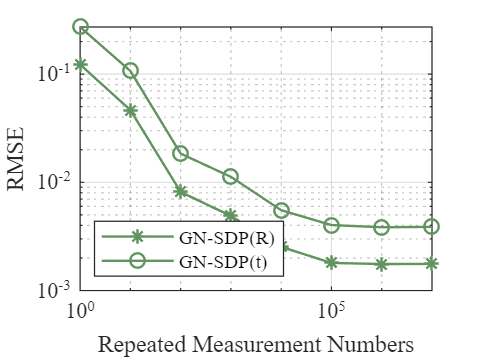

figure(1)
%GTRS
loglog(T,Y2_r(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#629460');
hold on
loglog(T,Y2_r(:,3),'-o','LineWidth',1,'MarkerSize',6,'Color','#629460');
hold off

set(gca,'Fontname', 'Times New Roman')
xlabel('Repeated Measurement Numbers')
ylabel('RMSE')
legend({'GN-SDP(R)','GN-SDP(t)'}, 'Location','southwest')
grid on

### 3.2 computation time for different methods

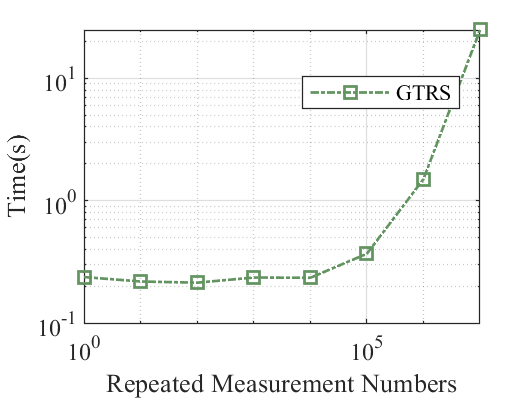

figure(3)
%GTRS
loglog(T,time_2,'-.s','LineWidth',1,'MarkerSize',6,'Color','#629460');
set(gca,'Fontname', 'Times New Roman')
xlabel('Repeated Measurement Numbers')
ylabel('Time(s)')
legend( 'GTRS','Location','Best')
grid on

save('time_GTRS.mat','time_2')